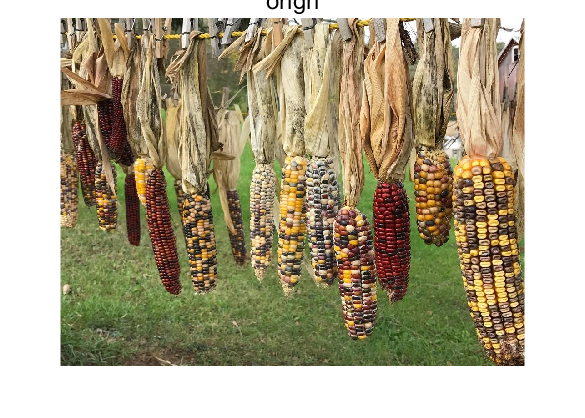

clc; clear;
img = imread("indiancorn.jpg");
[h, w, ~] = size(img);
%取5的倍数防止图像缩小再方法后大小对不上
img_orign = img(1:5*floor(h/5), 1:5*floor(w/5), :);
imshow(img_orign);
title("orign")

img = imresize(img_orign, 0.2);
R = 5;
N = 100; %每个插值函数跑100次和matlab内置的函数对比时间

%最近邻插值
t1 = clock;
for i=1:N
    img_near = nearest_neighbor(img, R);
end
t2 = clock;

t3 = clock;
for i=1:N
    img_near_m = imresize(img, R, "nearest");
end
t4 = clock;

my_t = etime(t2,t1)

my_t = 0.1100

matlab_t = etime(t4,t3)

matlab_t = 0.1540


my_psnr = psnr(img_near, img_orign)

my_psnr = 19.3798

matlab_pnsr = psnr(img_near_m, img_orign)

matlab_pnsr = 19.3798


my_ssim = ssim(img_near, img_orign)

my_ssim = 0.7339

matlab_ssim = ssim(img_near_m, img_orign)

matlab_ssim = 0.7339

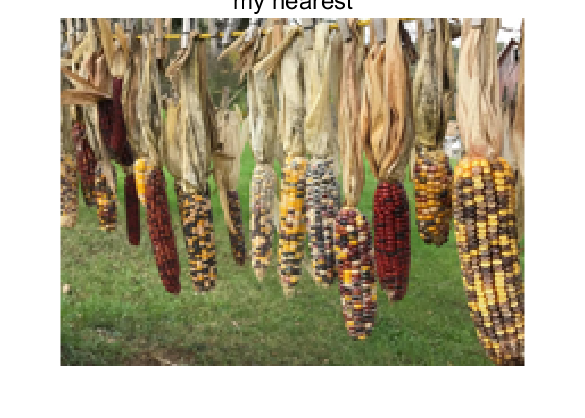


imshow(img_near)
title("my nearest")

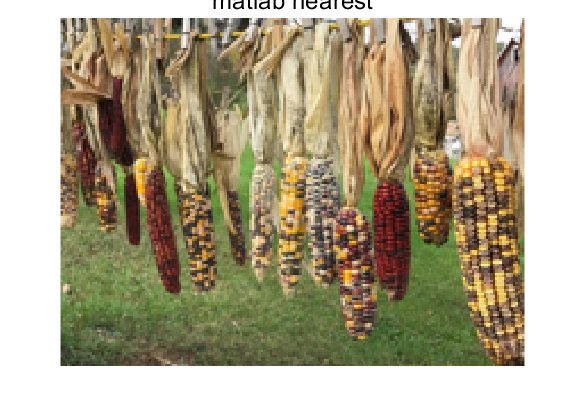

imshow(img_near_m)
title("matlab nearest")

%双线性插值
t1 = clock;
for i=1:N
    img_bilinear = bilinear_interpolation(img, R);
end
t2 = clock;

t3 = clock;
for i=1:N
    img_bilinear_m = imresize(img, R, "bilinear");
end
t4 = clock;

my_t = etime(t2,t1)

my_t = 3.1690

matlab_t = etime(t4,t3)

matlab_t = 0.1770


my_psnr = psnr(img_bilinear, img_orign)

my_psnr = 19.7757

matlab_pnsr = psnr(img_bilinear_m, img_orign)

matlab_pnsr = 19.7756


my_ssim = ssim(img_bilinear, img_orign)

my_ssim = 0.7528

matlab_ssim = ssim(img_bilinear_m, img_orign)

matlab_ssim = 0.7528

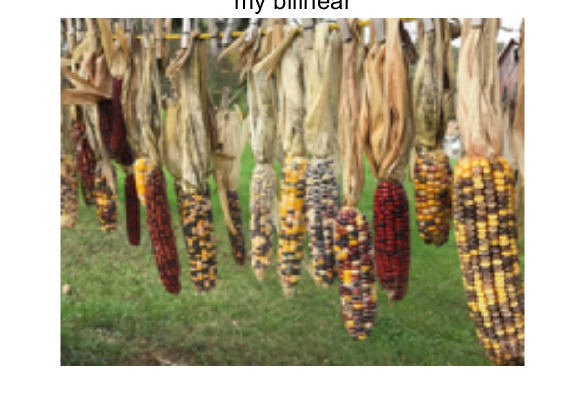


imshow(img_bilinear)
title("my bilinear")

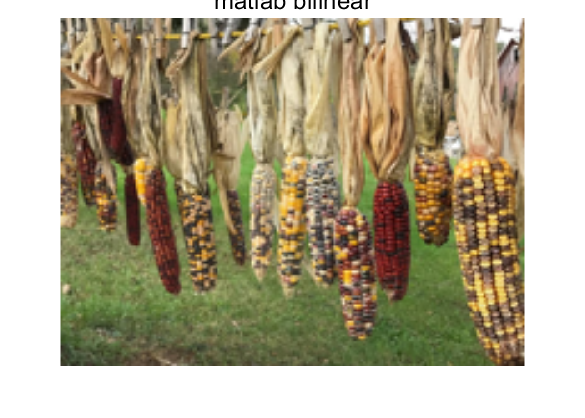

imshow(img_bilinear)
title("matlab bilinear")

%双三次插值
t1 = clock;
for i=1:N
    img_bicubic = bicubic_interpolation(img, R);
end
t2 = clock;

t3 = clock;
for i=1:N
    img_bicubic_m = imresize(img, R, "bicubic");
end
t4 = clock;

my_t = etime(t2,t1)

my_t = 13.1020

matlab_t = etime(t4,t3)

matlab_t = 0.2170


my_psnr = psnr(img_bicubic, img_orign)

my_psnr = 20.1147

matlab_pnsr = psnr(img_bicubic_m, img_orign)

matlab_pnsr = 20.1146


my_ssim = ssim(img_bicubic, img_orign)

my_ssim = 0.7649

matlab_ssim = ssim(img_bicubic_m, img_orign)

matlab_ssim = 0.7649

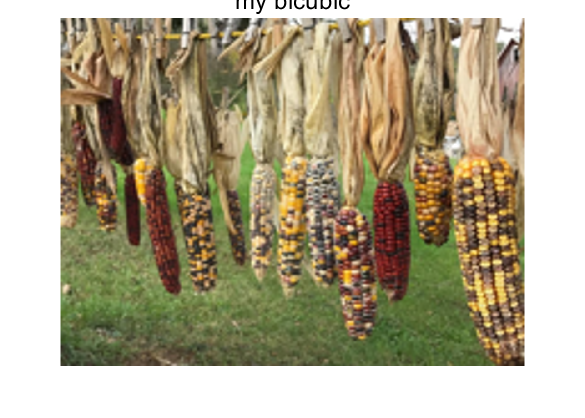


imshow(img_bicubic)
title("my bicubic")

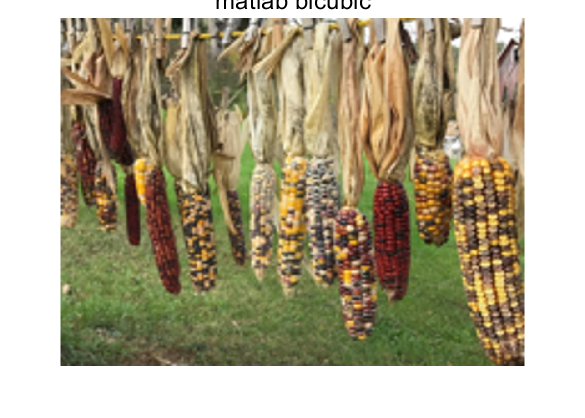

imshow(img_bicubic_m)
title("matlab bicubic")

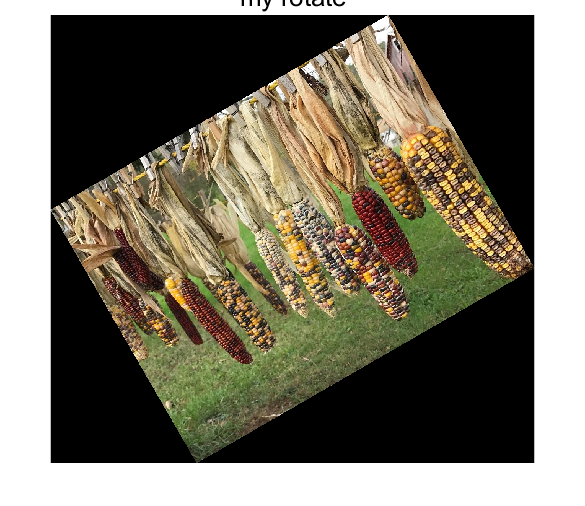

%图像旋转
img_rotate= rotate_image(img_orign, 30);
imshow(img_rotate)
title("my rotate")

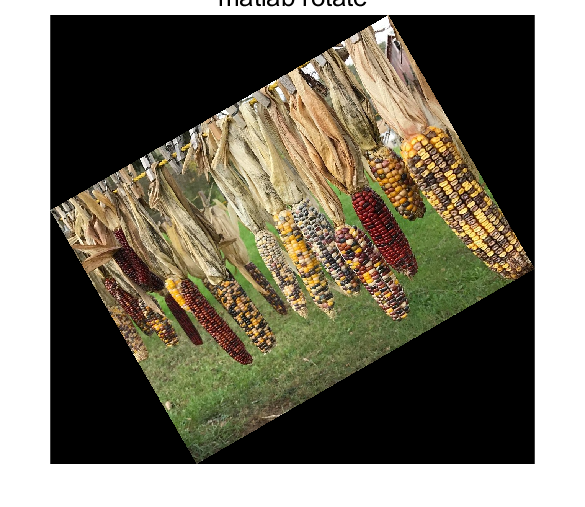

img_rotate_m = imrotate(img_orign, 30);
imshow(img_rotate_m)
title("matlab rotate")